# 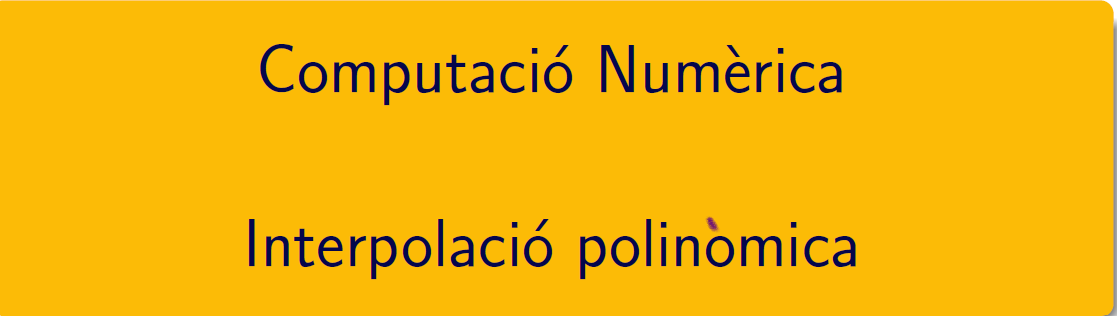

================================================================================

# Pràctica 9. Interpolació polinòmica i ajust de dades

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab9.pdf i en el document CN_full6.pdf, els podeu trobar en el campus virtual. 

## 1 APRENEM .....

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

p = [1 4 4 0];                       % vector amb els coeficients del polinomi 
r = roots(p); 
disp(['arrels = ', num2str(r')])   % arrels

arrels = 0 -2 -2


- avalueu el polinomi  $x^5-1$ per $x=2$

p = [1 0 0 0 0 -1 ];                 % vector amb els coeficients del polinomi 
v = polyval(p,2); 
disp(['valor = ', num2str(v)])      % valor polinomi

valor = 31


- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

r = [-5,-2,-1,1,2,8];               % vector amb les arrels
c = poly(r); 
disp(['coeficients = ',num2str(c)])   % coeficients polinomi d'arrels r

coeficients = 1   -3  -45   15  204  -12 -160


### Polinomi interpolador

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu la pàgina 5 i reproduïu el seu exemple. 

% x = 1:6;
% y = [16 18 21 17 15 12];
% disp([x; y])
% polyinterp(x,y,4.5)
% u = .75:.05:6.25;
% v = polyinterp(x,y,u);   
% plot(x,y,'o',u,v,'r-');

La rutina polyinterp.m obté els valors del polinomi interpolador (fórmula de Lagrange) de la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador.

#### Funcions de MATLAB® 

Els coeficients del polinomi interpolador es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

% x = 1:6;
% y = [16 18 21 17 15 12];
% disp([x; y])
% grau = length(x)-1
% p = polyfit(x,y,grau)  
% polyval(p,4.5)                         

**polyinterp de Moler = polyfit + polyval de MATLAB**

### Interpolació polinomial a trossos. 

% clearvars; 
% x = 1:6;
% y = [16 18 21 17 15 12];
% interpgui(x,y)

#### Diferències entre spline i pchip

% clearvars;
% x = 1: 8;
% y = zeros (1,8);
% y (4) = 1;
% interpgui(x, y)

#### Funcions de MATLAB® 

Per veure totes les possibilitats d'interpolació en MATLAB® consulteu la pàgina [interpolación](https://es.mathworks.com/help/matlab/interpolation.html) y més concretament la pàgina de la comanda [interp1](https://es.mathworks.com/help/matlab/ref/interp1.html), per obtenir un polinomi interpolador a trossos. Resum de de la comanda. 

Baixeu-vos del campus ***InterpolationofCoarselySampledSineFunctionExample.mlx, ***és el primer exemple de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline lineal i els valors de l'spline cúbic. 

% openExample('matlab/InterpolationofCoarselySampledSineFunctionExample')

#### Interpolació i extrapolació

Baixeu-vos del campus ***ExtrapolationUsingTwoDifferentMethodsExample.mlx*** . Aquest codi és de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline per avaluar punts que es troben fora del domini de x.

% openExample('matlab/ExtrapolationUsingTwoDifferentMethodsExample')

## 2 PRACTIQUEM ....

clearvars; clf

### 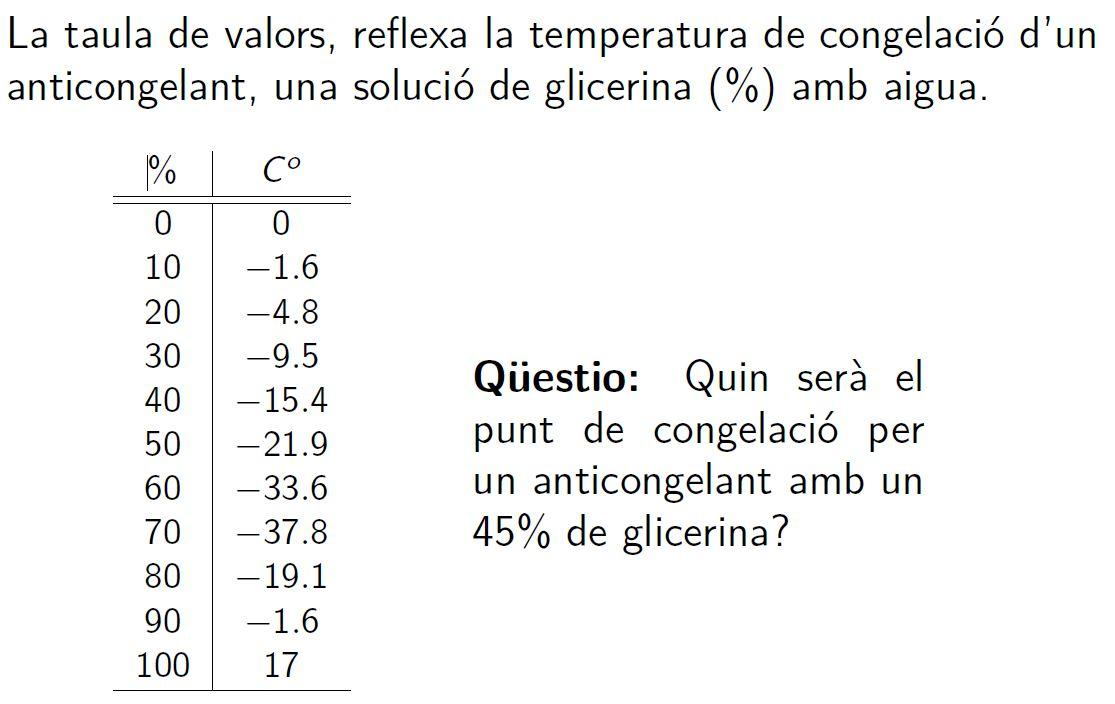

### Enunciat

Donar una estimació del punt de congelació per anticongelant amb **45%** de glicerol. Aquest exercici s'ha de resoldre fent ús de **polyinterp.**

- Gráfica de los datos

x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
plot(x,y,'*')

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')

#### Exercici 1. Interpolació lineal (recta)

- Valor aproximat polinomi

x1 = [40, 50];
y1 = [-15.4 -21.9];
valor_p1_45 = polyinterp(x1,y1,45)
disp(['valor = ',num2str(valor_p1_45)])

- Grafica de les dades, el valor aproximat i el polinomi interpolador

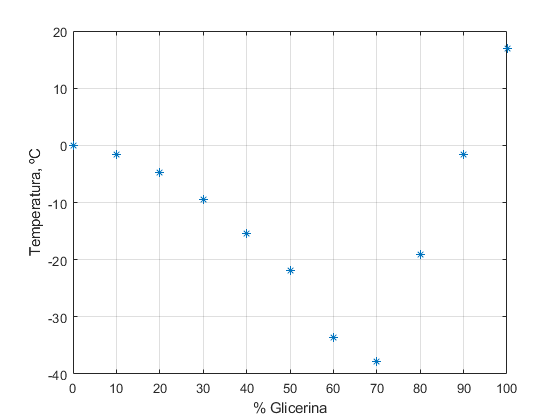

z = [25:65]; 
pz = polyinterp(x1,y1,z);
plot(z,pz,x,y,'*b',45,valor_p1_45,'*r','LineWidth',2)


grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Recta')

valor_p1_45 =        -18.65


#### Exercici 2. Polinomi interpolador de grau 3

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x = 0:10:100; 

valor = -18.65


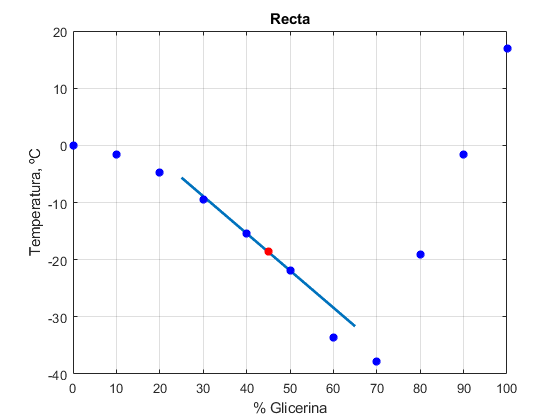

y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
x2 = [30, 40, 50, 60];
y2 = [-9.5 -15.4 -21.9 -33.6];
valor_p3_45 = polyinterp(x2,y2,45);
p3 = polyfit(x2,y2,3)
disp(['valor = ',num2str(valor_p3_45)])
z = [25:65]; 
pz = polyinterp(x2,y2,z);
plot(z,pz,x,y,'*b',45,valor_p3_45,'*r','LineWidth',2)


grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Cúbica')

#### Exercici 3. Polinomi interpolador de grau 10

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
valor_p10_45 = polyinterp(x,y,45);
disp(['valor = ',num2str(valor_p10_45)])

p3 =   -0.00076667        0.089      -3.9833         50.6


z = [0:100]; 

valor = -18.2875


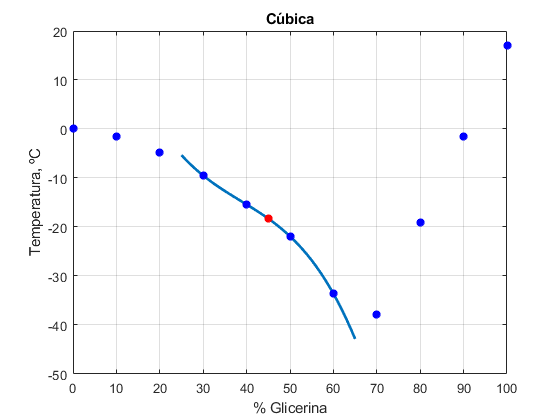

pz = polyinterp(x,y,z);
plot(z,pz,x,y,'*b',45,valor_p10_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Polinomi grau 10')
% No sembla un bon model en les puntes, no té sentit que al afegir

% glicerina es congeli en temperatura ambient (0-10% glicerina)

#### Exercici 4. Spline lineal  (interpolació lineal a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

valor_sl_45 = interp1(x,y,45);

valor = -18.1071


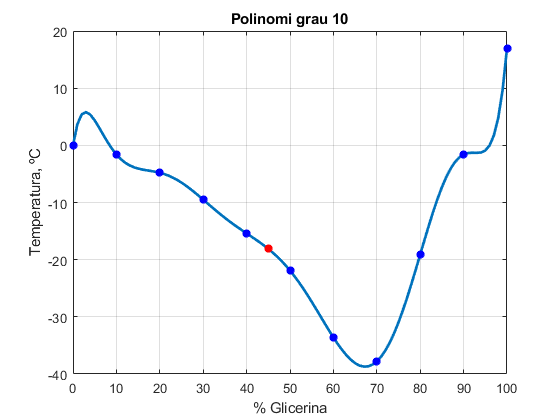

disp(['valor = ',num2str(valor_sl_45)])
z = [0:100]; 
pz = interp1(x,y,z);
plot(z,pz,x,y,'*b',45,valor_sl_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')

title('Spline lineal')

#### Exercici 5. Spline cúbic  (interpolació cúbica a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

valor_sc_45 = interp1(x,y,45,'spline');
disp(['valor = ',num2str(valor_sc_45)])

valor = -18.65


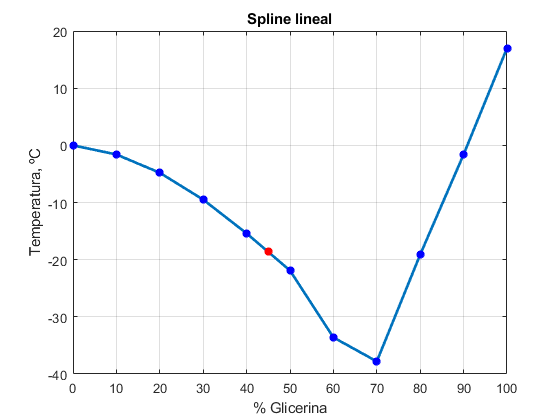

z = [0:100]; 
pz = interp1(x,y,z,'spline');
plot(z,pz,x,y,'*b',45,valor_sc_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Spline natural')

x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

valor_sc_45 = interp1(x,y,45,'pchip');
disp(['valor = ',num2str(valor_sc_45)])

valor = -18.1816


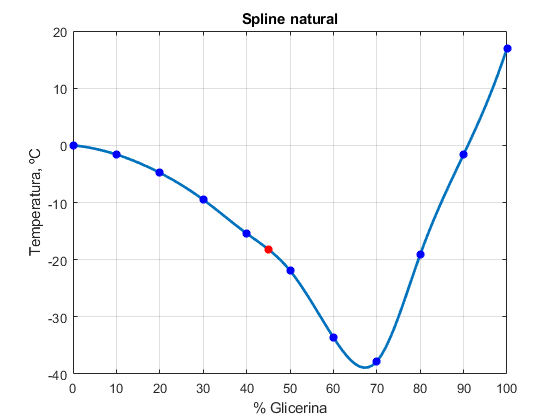

z = [0:100]; 
pz = interp1(x,y,z,'pchip');
plot(z,pz,x,y,'*b',45,valor_sc_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Spline pchip')

#### Exercici 6. Ajust per mínims quadrats (recta)

- Valor aproximat recta

- Grafica de les dades, el valor aproximat i el polinomi interpolador

clearvars;
x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
r = polyfit(x,y,1)
r_45 = polyval(r,45)

valor = -18.3785


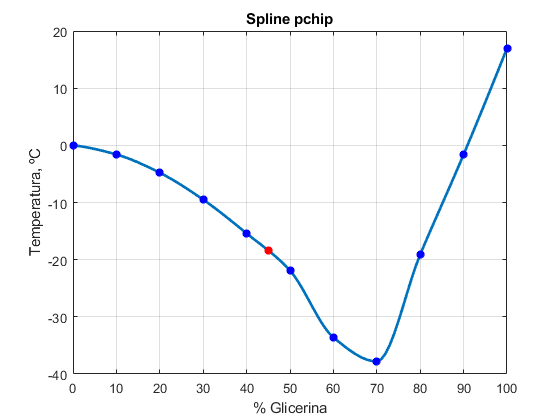

z = [0:100]; 
pz = polyval(r,z);
plot(z,pz,x,y,'*b',45,r_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Recta mínims quadrats')

#### Exercici 7. Ajust per mínims quadrats (cúbica)

- Valor aproximat cúbica

- Grafica de les dades, el valor aproximat i el polinomi interpolador

clearvars;
x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
q = polyfit(x,y,3)

r =     -0.029727      -10.177


q_45 = polyval(q,45)

r_45 =       -11.515


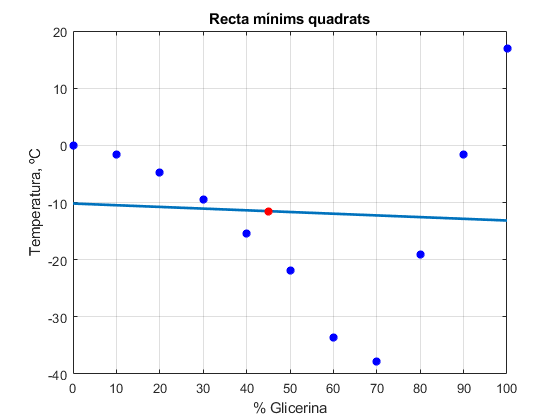

z = [0:100]; 
pz = polyval(q,z);
plot(z,pz,x,y,'*b',45,q_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Cúbica mínims quadrats')

#### Exercici 8. Interpolació des de la finestra de gràfics

Representeu gràficament la taula de dades, cada node per un *, a continuació mitjançant el menú Tools de la finestra gràfica accediu a l'opció basic fitting i trobeu una corba que ajusti les dades.

clearvars;
x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

### Exercici 9. Interpolació inversa

Aplicació de la interpolació al càlcul de zeros de funcions.

clearvars;

q =    0.00033611     -0.03639      0.49015      -1.2371


f = @(x)x-cos(x); 

q_45 =       -22.242


fplot({f,0},[-2,2],'LineWidth',2),grid,legend('Location','bestoutside')
raiz = fzero(f,1)
xnodes = [0.5,0.75,1.25]';
ynodes = f(xnodes); disp([xnodes,ynodes])
arrel = polyinterp(ynodes,xnodes,0)     % fixar-se que les x i y estan en pos canviades
arrel = interp1(ynodes,xnodes,0,'pchip')
 p_arrel = polyfit(ynodes,xnodes,2); arrel = polyval(p_arrel,0)

### Exercici 10. Extrapolació

Què s'enten per extrapolació?

Exemple de Cleve Moler, [Census 2017](https://es.mathworks.com/company/newsletters/articles/fitting-and-extrapolating-u-s-census-data.html) i [Census 2020](https://blogs.mathworks.com/cleve/2020/11/06/anticipating-official-u-s-census-for-2020/)

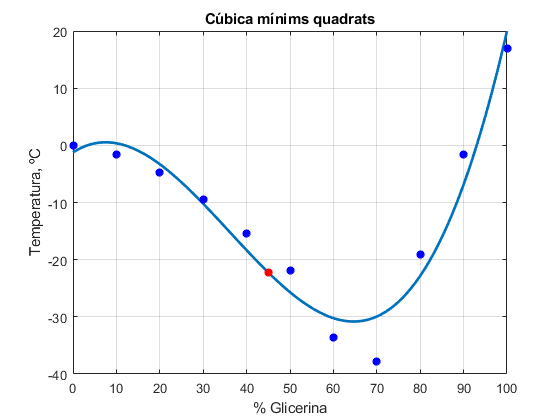

clf, clearvars, format short g

load dades.mat
disp([cdate,pop])
plot(cdate,pop,'*')

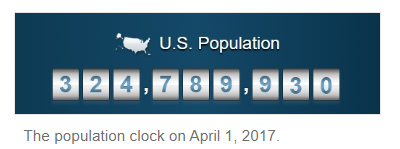

valor_lineal = interp1(cdate,pop,2017,'linear','extrap')
valor_polinomi = polyinterp(cdate,pop,2017)     % El polinomis interpoladors no serveixen per predir fora del rang
valor_spline = interp1(cdate,pop,2017,'spline')
valor_pchip = interp1(cdate,pop,2017,'pchip')
% [p,mu] = polyfit(x,y,grau)        canvi de escala x molt grans
% valor = polyval(p,_,mu)
% APPS - Curve Fitting

## 3 Codi funcions: polyinterp 

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab"  (*pàgina 5). 

La rutina polyinterp.m obté els valors del polinomi interpolador (fórmula de Lagrange) de la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

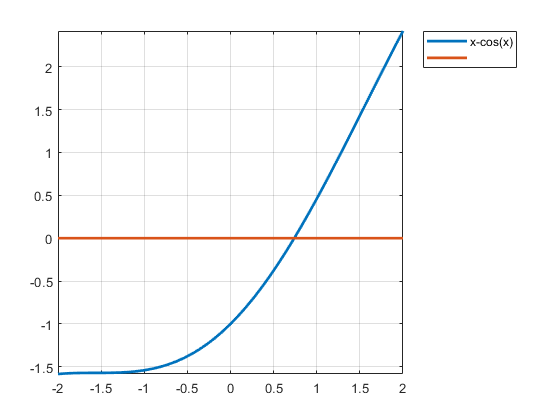

function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.

%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the

raiz =       0.73909


%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).


          0.5     -0.37758
         0.75     0.018311
         1.25      0.93468



%   Copyright 2014 Cleve Moler

arrel =       0.73889


%   Copyright 2014 The MathWorks, Inc.

arrel =       0.73913


arrel =       0.73889


% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.

n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));

         1900       75.995
         1910       91.972
         1920       105.71
         1930        123.2
         1940       131.67
         1950        150.7
         1960       179.32
         1970       203.21
         1980        226.5
         1990       249.63
         2000       281.42
         2010       308.75



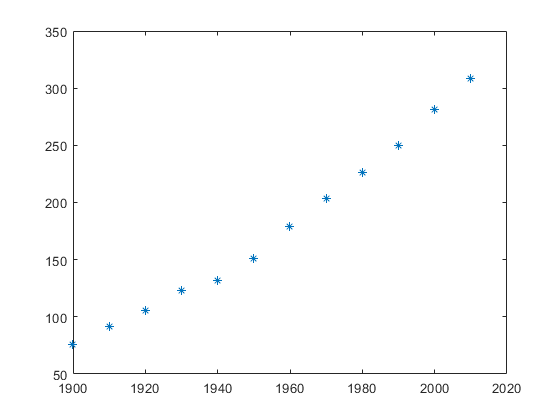

   for j = [1:k-1 k+1:n]

      w = (u-x(j))./(x(k)-x(j)).*w;
   end

valor_lineal =        327.87


   v = v + w*y(k);

valor_polinomi =       -385.06


end

valor_spline =        314.62


end

valor_pchip =        325.08
